# Laboratory Block 1: Signals and Systems

Fink Lucas, 06.11.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Example 1: Special Signals


$$\delta \left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1, & \mathrm{if}\;n=0\\
0, & \mathrm{if}\;n\not= 0
\end{array}\right.$$



$$u\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1, & \mathrm{if}\;n\ge 0\\
0 & \mathrm{if}\;n<0
\end{array}\right.$$


vn = -20:1:20

vn =    -20.0000e+000   -19.0000e+000   -18.0000e+000   -17.0000e+000   -16.0000e+000   -15.0000e+000   -14.0000e+000   -13.0000e+000   -12.0000e+000   -11.0000e+000   -10.0000e+000    -9.0000e+000    -8.0000e+000    -7.0000e+000    -6.0000e+000    -5.0000e+000    -4.0000e+000    -3.0000e+000    -2.0000e+000    -1.0000e+000     0.0000e+000     1.0000e+000     2.0000e+000     3.0000e+000     4.0000e+000     5.0000e+000     6.0000e+000     7.0000e+000     8.0000e+000     9.0000e+000    10.0000e+000    11.0000e+000    12.0000e+000    13.0000e+000    14.0000e+000    15.0000e+000    16.0000e+000    17.0000e+000    18.0000e+000    19.0000e+000    20.0000e+000


function [unitStep] = heavisideFunction(vn)
    unitStep = zeros(size(vn));
    unitStep(vn >= 0) = 1;
end

function [deltaFunc] = deltaFunction(vn)
    deltaFunc = zeros(size(vn));
    k = find(vn == 0);
    deltaFunc(k) = 1;
end

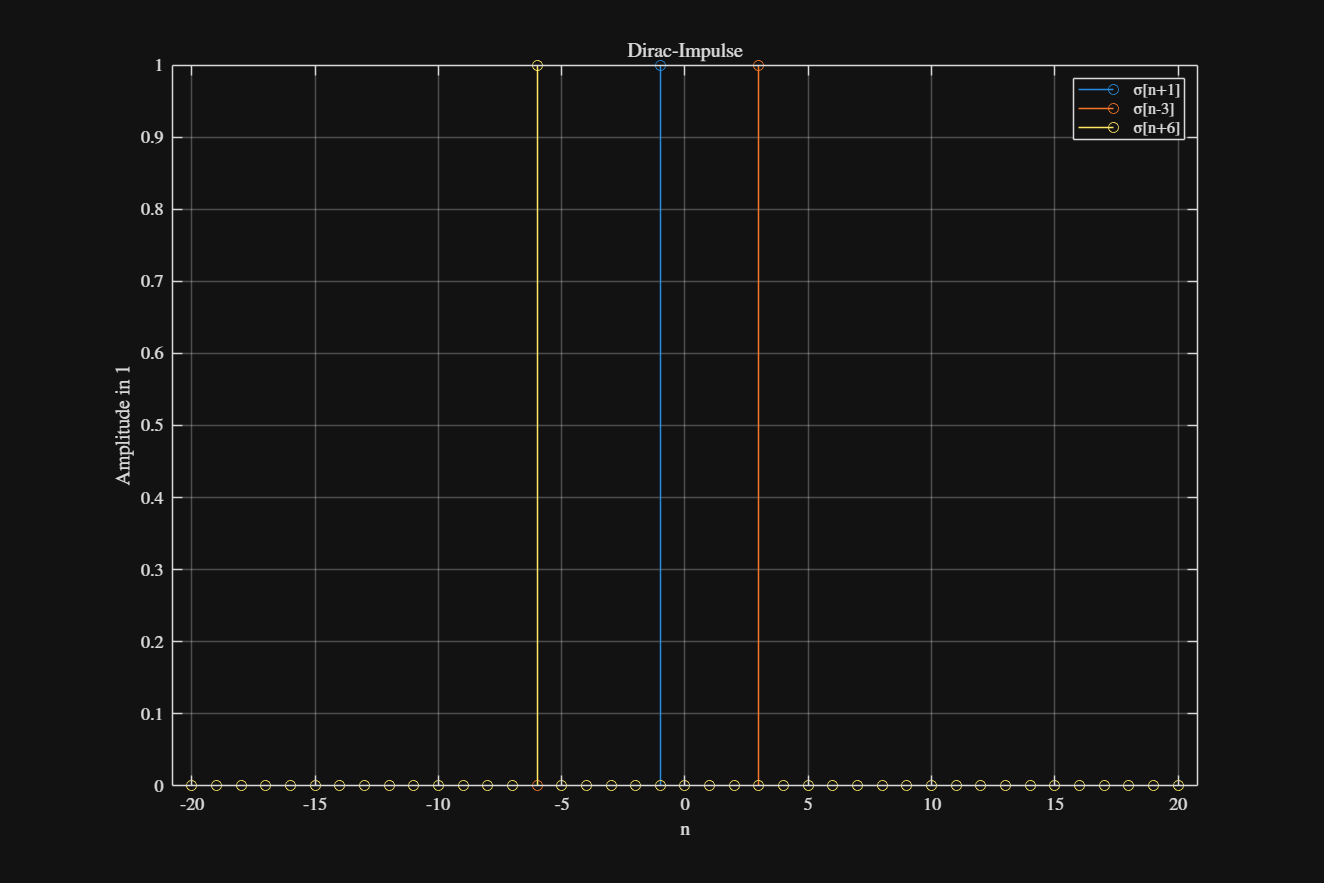

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
stem(vn, deltaFunction(vn+1))
hold on
stem(vn, deltaFunction(vn-3))
stem(vn, deltaFunction(vn+6))
hold off
xlabel('n')
ylabel('Amplitude in 1')
title('Dirac-Impulse')
legend('σ[n+1]','σ[n-3]', 'σ[n+6]')
grid on

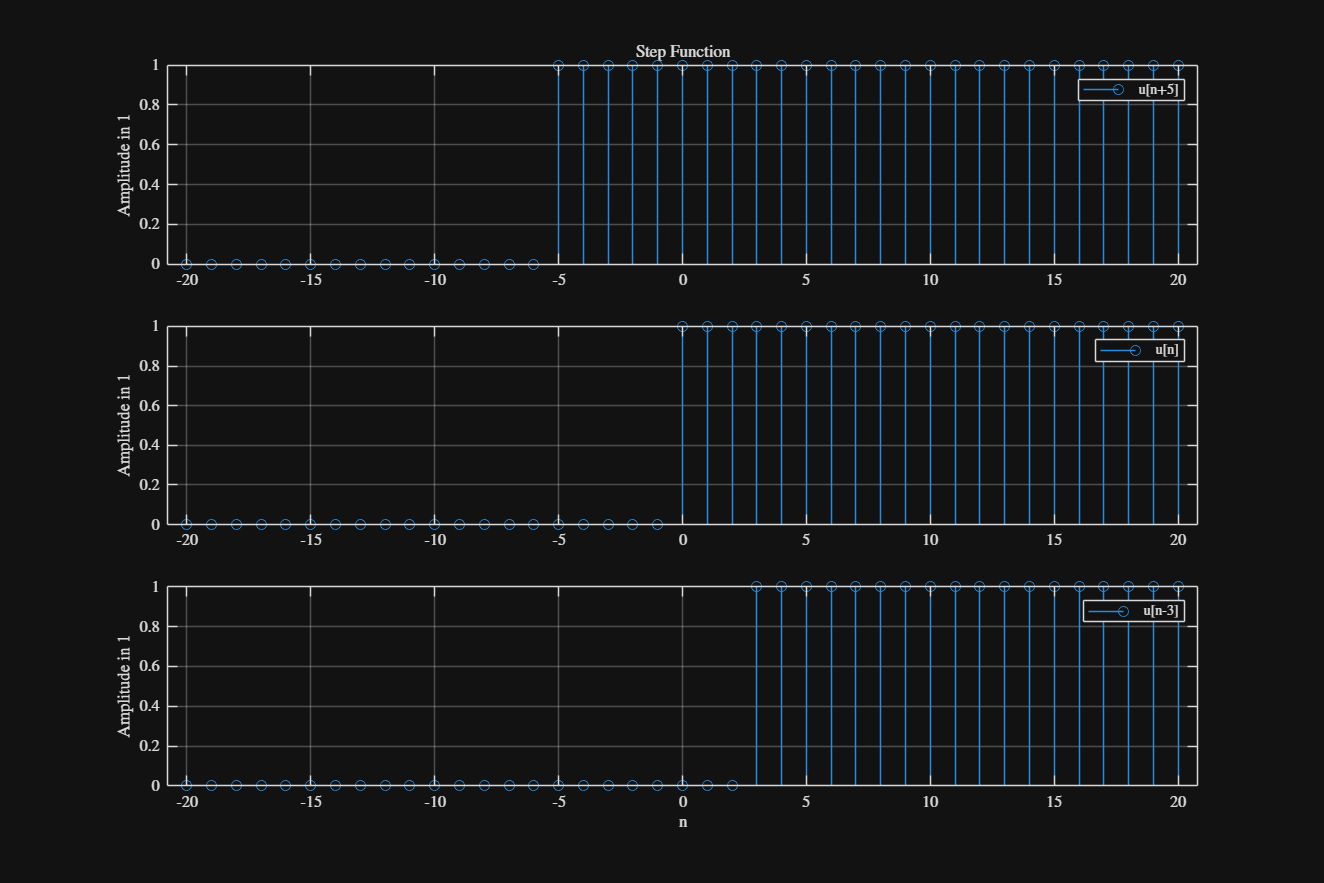

heavisideFunc1 = heavisideFunction(vn+5);
heavisideFunc2 = heavisideFunction(vn);
heavisideFunc3 = heavisideFunction(vn-3);

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(3, 1)  
nexttile
stem(vn, heavisideFunc1)
ylabel('Amplitude in 1')
title('Step Function')
legend('u[n+5]')
grid on

nexttile
stem(vn, heavisideFunc2)
ylabel('Amplitude in 1')
legend('u[n]')
grid on

nexttile
stem(vn, heavisideFunc3)
hold off
ylabel('Amplitude in 1')
xlabel('n')
legend('u[n-3]')
grid on

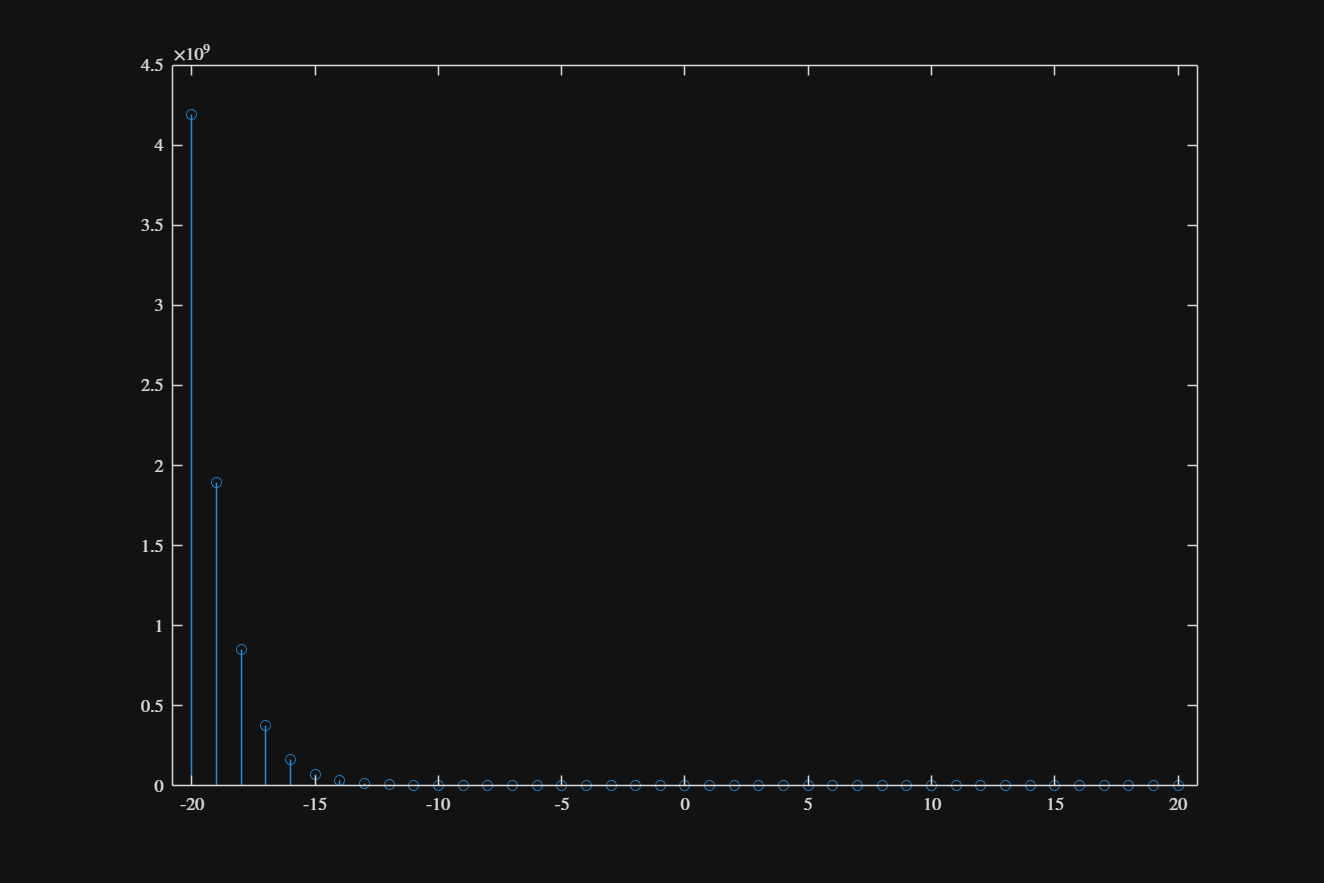

mixed = 3 * deltaFunction(vn + 1) + vn.^2 .* (heavisideFunction(vn + 5) - heavisideFunction(vn + 4) + 10*(0.5).^vn);

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
stem(vn, mixed)

## Example 2: Representation of DT Signals

### a) Writing a Function which calculates the even $x_e \left\lbrack n\right\rbrack$ and odd part $x_o \left\lbrack n\right\rbrack$ of the signal $x\left\lbrack n\right\rbrack$

vx = (-0.2 + 1j*0.3).^vn .* sin(pi / 4 .* vn ) .* (heavisideFunction(vn +3) - heaviside(vn - 5));

function [vxe,vxo]=analyzeSignal(vn,vx)
    vx_neg_vn = fliplr(vx);
    vxe = 0.5 *(vx + vx_neg_vn);
    vxo = 0.5 *(vx - vx_neg_vn);
end


### b) Plotting the real part and the imaginary part of $x_e \left\lbrack n\right\rbrack$

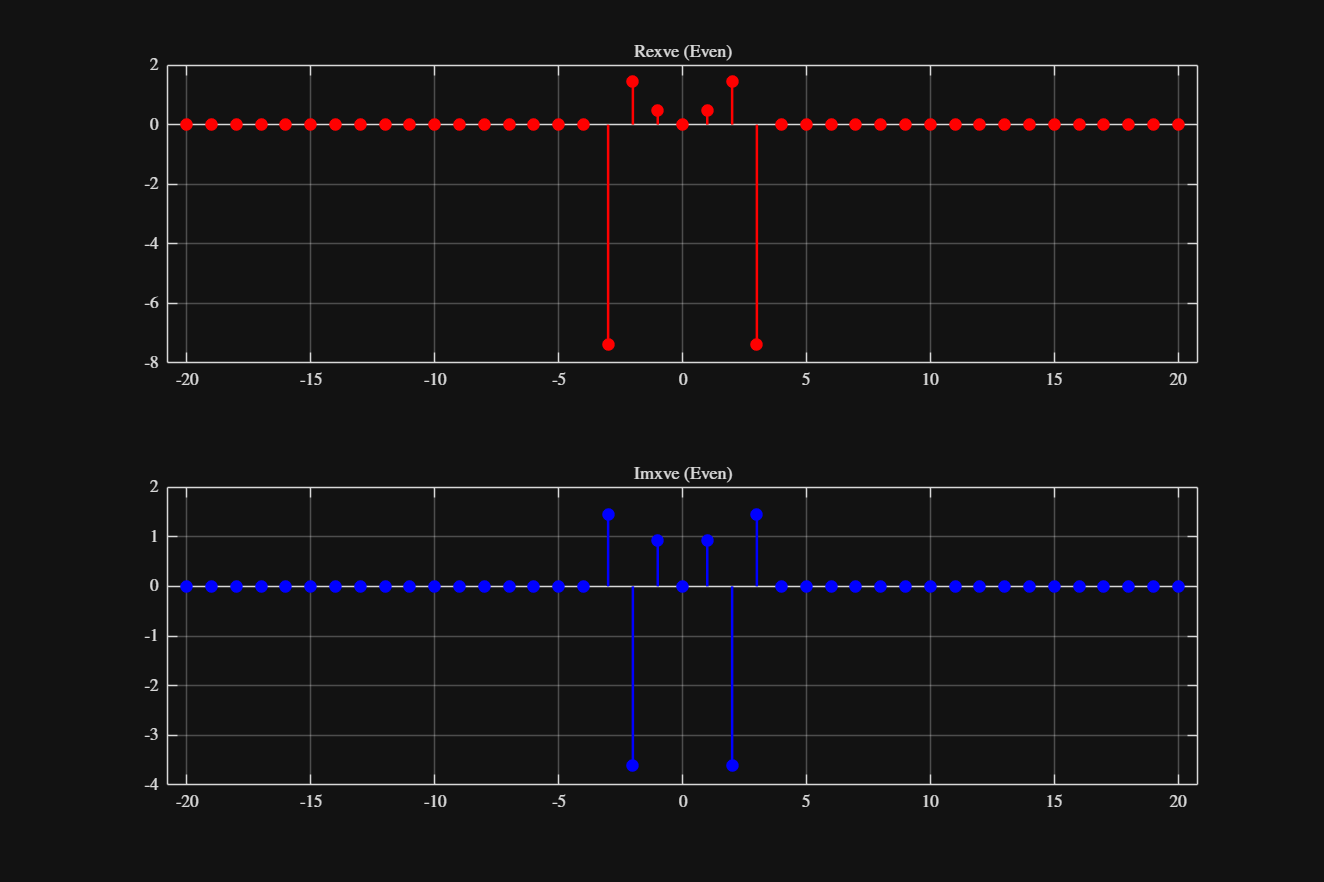

[vxe, vxo] = analyzeSignal(vn, vx);

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2, 1)  
nexttile
stem(vn, real(vxe), 'filled', 'r', 'LineWidth', 1.5);
title('Re{xve} (Even)');
grid on;
nexttile
stem(vn, imag(vxe), 'filled', 'b', 'LineWidth', 1.5);
title('Im{xve} (Even)');
grid on;

### c) Plotting the real part and the imaginary part of $x_o \left\lbrack n\right\rbrack$

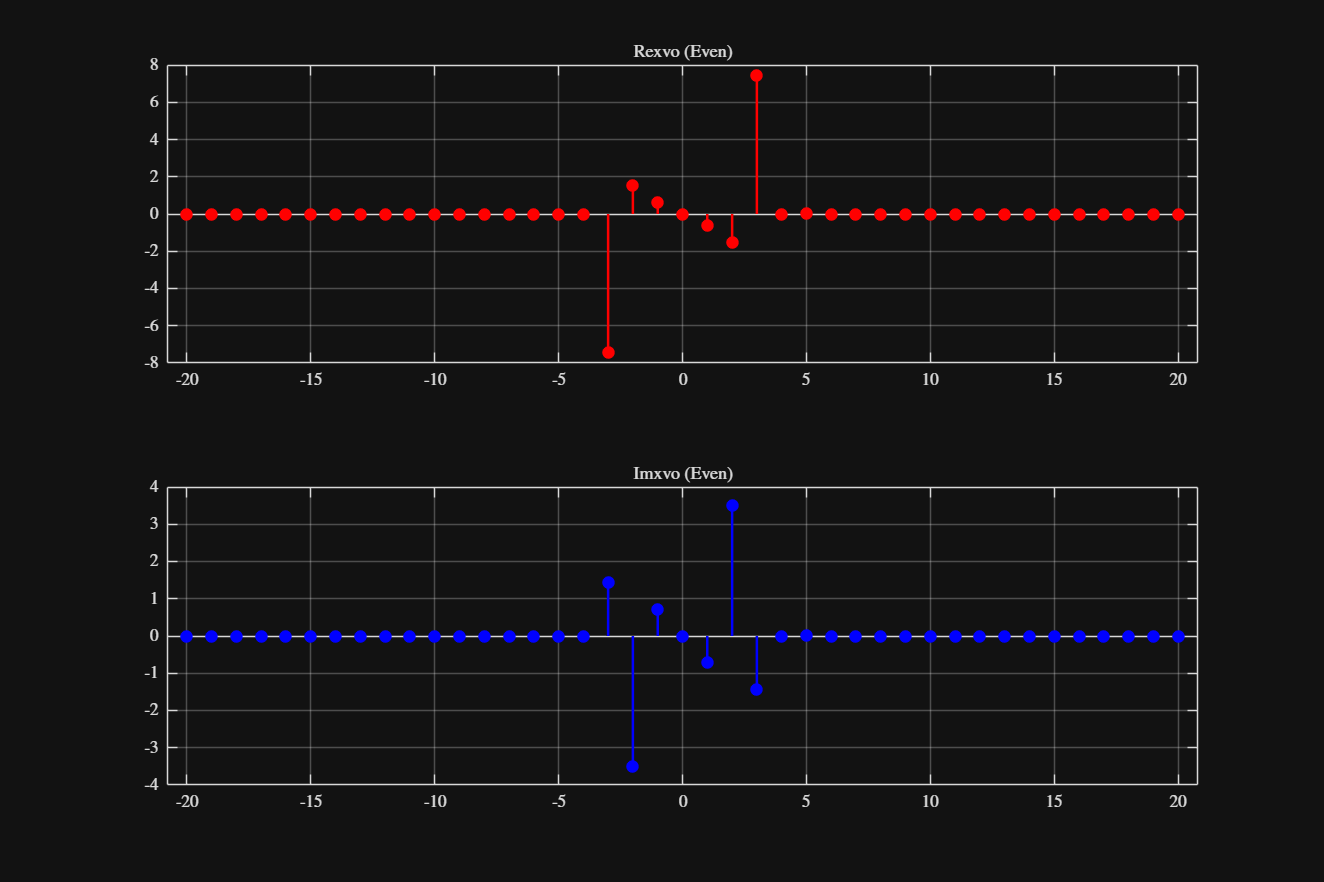

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2, 1)  
nexttile
stem(vn, real(vxo), 'filled', 'r', 'LineWidth', 1.5);
title('Re{xvo} (Even)');
grid on
nexttile
stem(vn, imag(vxo), 'filled', 'b', 'LineWidth', 1.5);
title('Im{xvo} (Even)');
grid on;

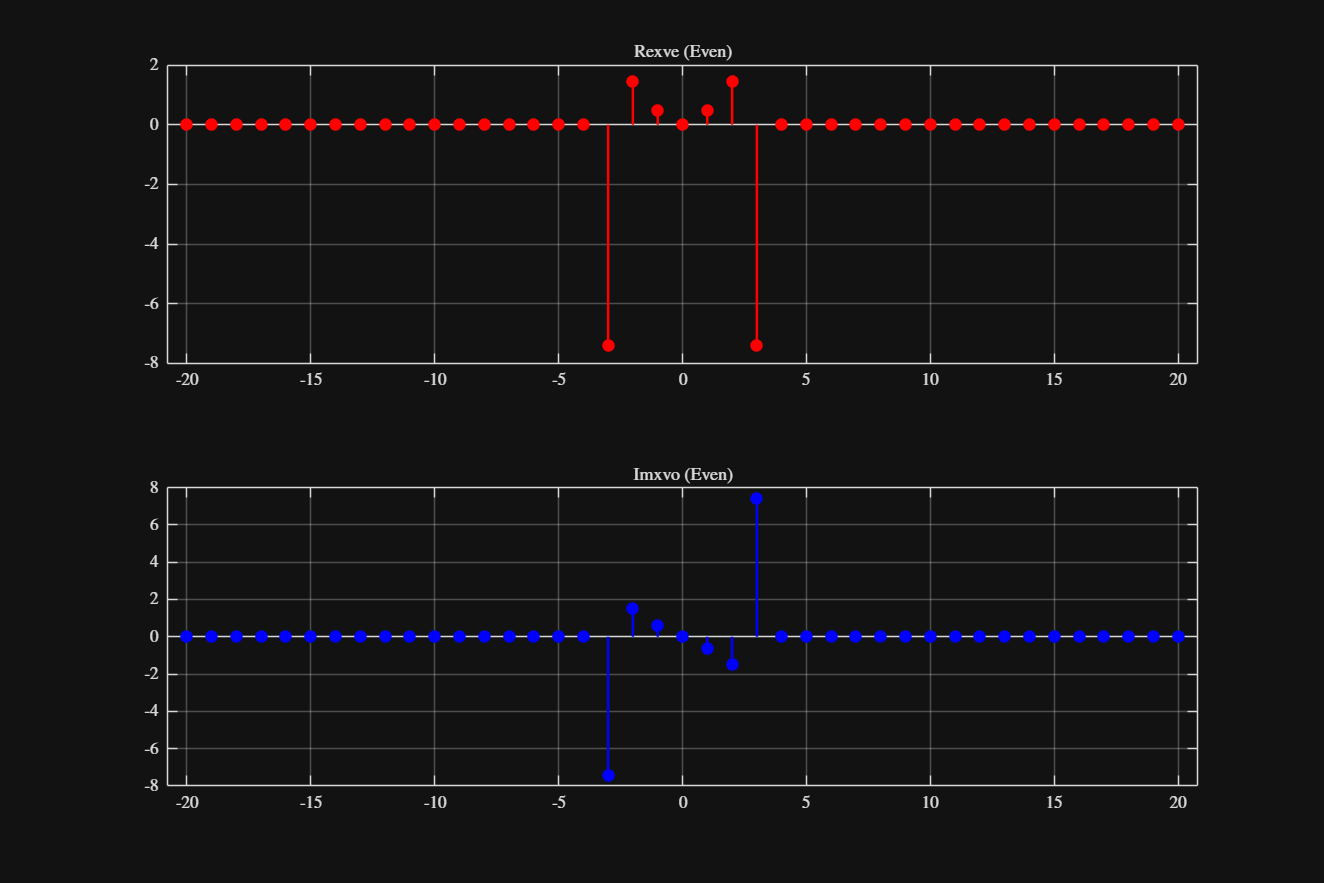

vxr = real(vx);


[vx_r_e, vx_r_o] = analyzeSignal(vn, vxr);

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2, 1)  
nexttile
stem(vn, vx_r_e, 'filled', 'r', 'LineWidth', 1.5);
title('Re{xve} (Even)');
grid on;
nexttile
stem(vn, vx_r_o, 'filled', 'b', 'LineWidth', 1.5);
title('Im{xvo} (Even)');
grid on;

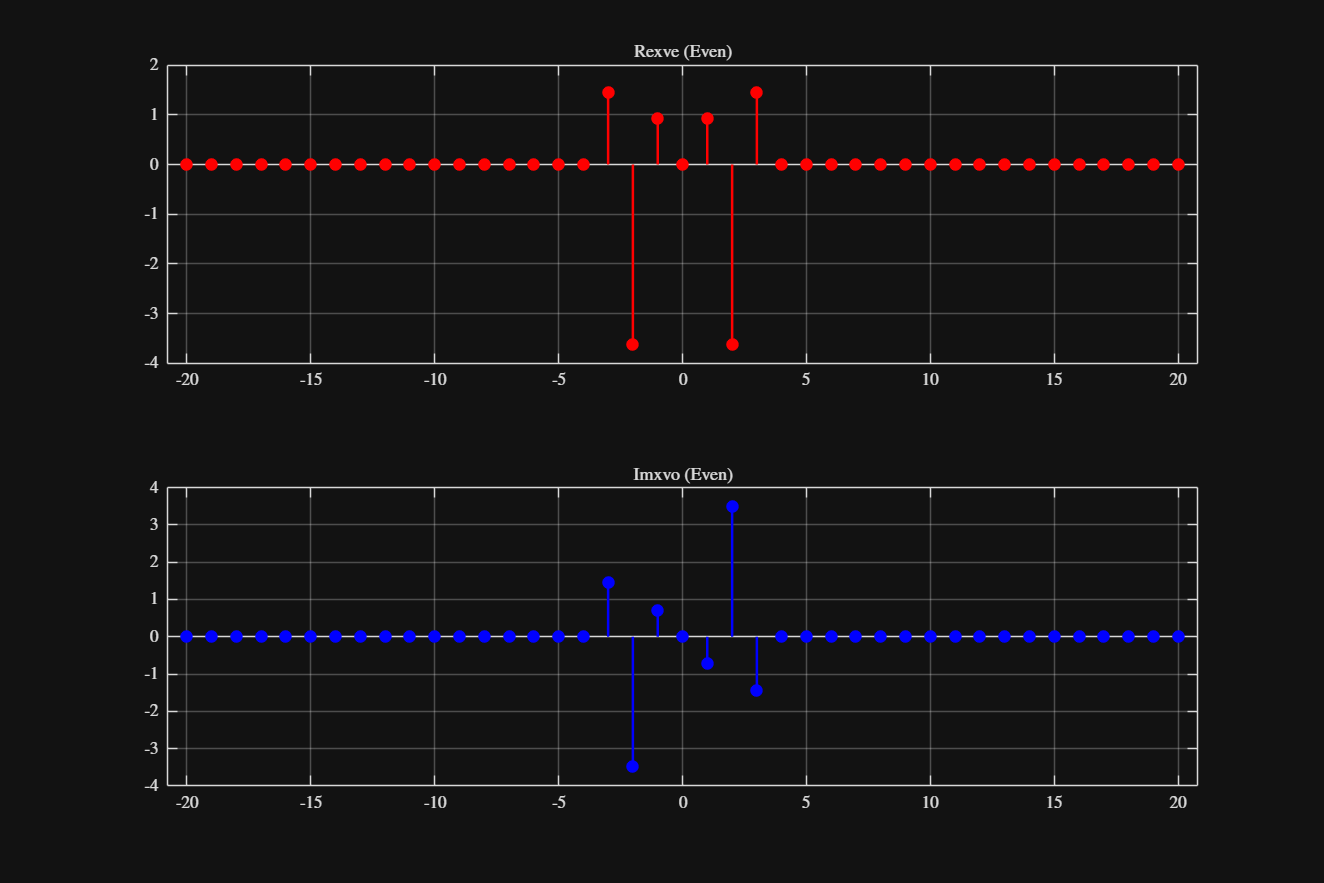

vjxi = imag(vx);

[vx_i_e, vx_i_o] = analyzeSignal(vn, vjxi);

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2, 1)  
nexttile
stem(vn, vx_i_e, 'filled', 'r', 'LineWidth', 1.5);
title('Re{xve} (Even)');
grid on;
nexttile
stem(vn, vx_i_o, 'filled', 'b', 'LineWidth', 1.5);
title('Im{xvo} (Even)');
grid on;

clearvars -except vn

## Example 3: Concolution

vxn = [1, 5, -1, 6, 3];


### a) Determining the impulse response $h\left\lbrack n\right\rbrack$ of the given system, analytically

hn = [3, 0, -4, 0, 6]

hn =      3.0000e+000     0.0000e+000    -4.0000e+000     0.0000e+000     6.0000e+000


### b) Writing a function which calculates the convolution of the input vectors

function  [vconOut] = convASP(vInput1, vInput2)
    vconOut = vInput1 * vInput2;
end